## **MFPT Analysis for Ghost Attractor Model**

**Purpose:** Find the pdf, cdf, reliability function, and mfpt for our Ghost Attractor Model. 

**Methods: **Use pdepe, cumtrapz & trapz. Results follow from analysis done in paper.

**Run Time: **Seconds.

clear;

%Pick Cartesian Coordinates (See pdepe syntax if unfamiliar & concerned)
m = 0;

%Define space & time domains
x0 = linspace(0,.9798,500);
t = linspace(0,5000,500);

%Solve the pde
sol = pdepe(m,@eqn,@ic,@bc,x0,t);

%Show that the soluiton is a CDF
disp("Observe that the max of sol is " + max(sol,[],"all") + " which is consistent.");

Observe that the max of sol is 1 which is consistent.


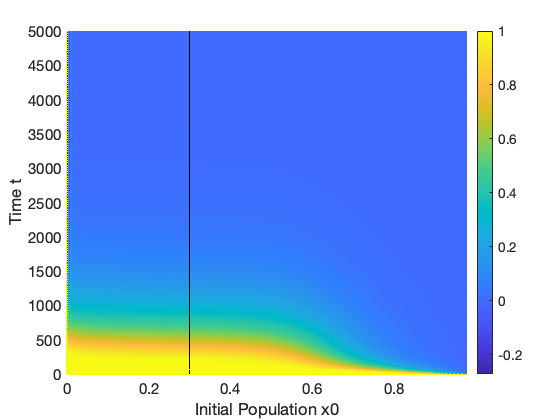


%%%%%%%%%%%%%%%%%%%%%%%Plotting%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
mesh(x0,t,sol);   
colorbar;
hold on;

%Limit & Lable Preferences
xlabel('Initial Population x0','FontSize',20);
xlim([0,.9798]);
ylabel('Time t','FontSize',20);
zlabel('Probability');
ax = gca;
ax.FontSize = 15;

%Draw Cross Section
patch([.3,.3,.3,.3],[0,5000,5000,0],[0,0,1,1],'r','facealpha',.5);
view(2);

%We Examine the Cross Section Marked in the Above Figure (x0 = .3)

%Look at Solution when x0 = .3
disp("Index @ 154 is " + x0(154) + " which is approximately .3");

Index @ 154 is 0.30042 which is approximately .3


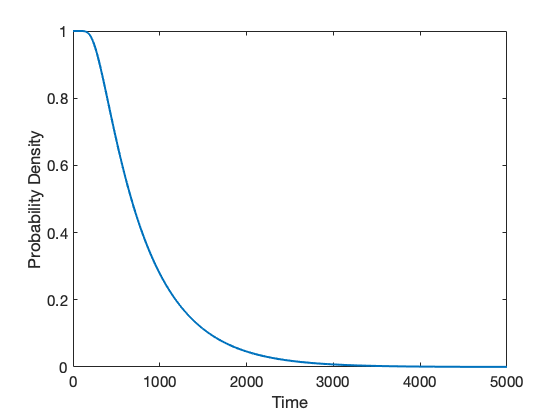


%Retrieve the Reliability Function @ x0 = .3
reliability = sol(:,154);

%Plot it & Lable it
nexttile;
plot(t,reliability,'LineWidth',2);
xlabel('Time','FontSize',17);
ylabel('Probability Density','FontSize',17);
ax = gca;
ax.FontSize = 15;

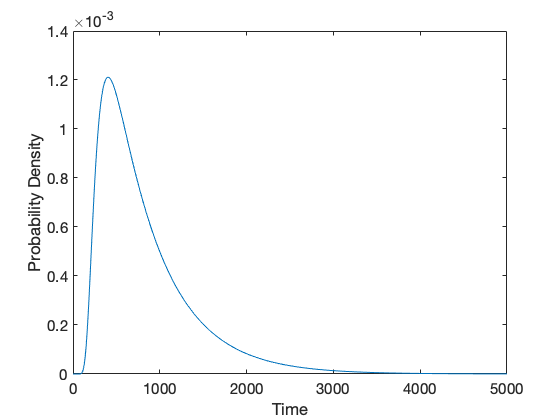

%We Attain the First Passage Time PDF

%Calculate the pdf (gradient should take a numerical time derivative)
pdf = -gradient(reliability,t);

%Plot & Lable
figure;
plot(t,pdf);
xlabel('Time',"FontSize",17);
ylabel('Probability Density','FontSize',17);
ax = gca;
ax.FontSize = 15;


%Notice that Numerical integration converges to 1 like a pdf should
disp("Observe the integral of this function is: " + trapz(t,pdf));

Observe the integral of this function is: 0.99979


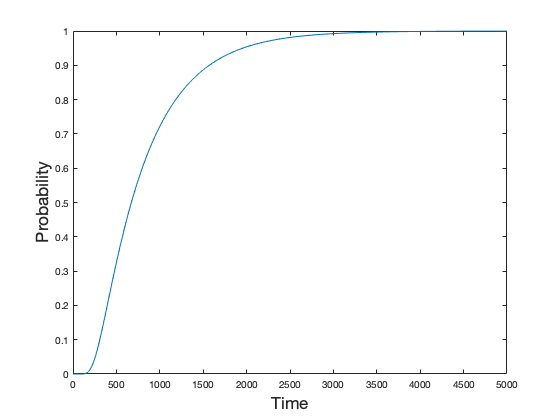

%We Attain the CDF of the First Passage Time

%Calculate cdf (Integrates Up to Specified t Value, Cumulative Integration)
cdf = cumtrapz(t,pdf);

figure;
plot(t,cdf);
xlabel('Time',"FontSize",17);
ylabel('Probability','FontSize',17);

%We Calculate the Mean First Passage Time or the Expectation of the
%Passage Time

% Make 0 vector of appropriate length
expf = 0*pdf;

% Get X*f(x) points
for i = 1: length(pdf)
    
    expf(i) = pdf(i)*t(i);
end

% Integrate over X*f(x) to get Expectation
expectation = trapz(t,expf);

% Display
disp("The Mean First Passage Time is " + expectation);

The Mean First Passage Time is 831.5775


**Notes on Functions: **eqn is the PDE, u0 is the initial condition function, and bc is the Boundary Condition Functions

function [c,f,s] = eqn(x0,t,P,DPDx0)

%Parameters
r = .05;
K = 2;
a = .023;
h = .38;
q = 5;
phi = .02;

%Time Derivative is Not Scaled
c = 1;

%Diffusion Vector Transformed for BK
f = DPDx0*(.5*phi^(2)*x0^(2));

%Drift Vector Transformed for BK
s = (r*x0*(1-(x0/K)) - (a*x0^(q))/(x0^(q) + h^(q)) - (phi^(2) * x0))*DPDx0;

end

function u0 = ic(x0)

%The probability we're in target region at t = 0 is 1 
%Independent of the x0
u0 = 1;

end


function [pl,ql,pr,qr] = bc(x0l,Pl,x0r,Pr,t)

%Probability of Being in Target Space if we Start @ 0 for any time is 1
%given 0 should act like a steady state
pl = 1-Pl;
ql = 0;

%Probability of Being in Target Space if we Start @ mu = 0
pr = Pr;
qr = 0;
end






